
% PM1 = 1:65; % Indices for time periods Not a full night 
PM2 = 185:307;
PM3 = 426:547;
PM4 = 666:787;
% PM5 = 906:958;

AM1 = 66:184; 
AM2 = 308:425;
AM3 = 548:665;
AM4 = 788:905;


Unrecognized function or variable 'delDOdtmean'.

NEP1 = sum(delDOdtk(AM1))/10 

NEP1 = 104.4372

NR2 = nansum(delDOdtk(PM2))/10 %mmol/m2/hr % changed to 10 because 10 readings in an hour 

NR2 = -59.3388

NEP2 = sum(delDOdtk(AM2))/10 

NEP2 = 92.7075

NR3 = sum(delDOdtk(PM3))/10 %mmol/m2/hr 

NR3 = -80.9305

NEP3 = sum(delDOdtk(AM3))/10 %mmol/m2/hr 

NEP3 = 138.7249

NR4 = sum(delDOdtk(PM4))/10 %mmol/m2/hr 

NR4 = -121.5216

NEP4 = sum(delDOdtk(AM4))/10 %mmol/m2/hr 

NEP4 = 7.7872


NEM1 = NEP1 + NR2

NEM1 = 45.0984

NEM2 = NEP2 + NR3

NEM2 = 11.7770

NEM3 = NEP3 + NR4

NEM3 = 17.2033


meanR2 = nanmean(delDOdtk(PM2))

meanR2 = -7.6075

meanR3 = nanmean(delDOdtk(PM3))

meanR3 = -6.6336

meanR4 = nanmean(delDOdtk(PM4))

meanR4 = -9.9608


DRR2 = meanR2*24

DRR2 = -182.5809

DRR3 = meanR3*24

DRR3 = -159.2075

DRR4 = meanR4*24

DRR4 = -239.0589


GPP1 = NEP1 + length(AM1)/10*abs(meanR2)

GPP1 = 194.9669

GPP2 = NEP2 + length(AM2)/10*abs(meanR3)

GPP2 = 170.9845

GPP3 = NEP3 + length(AM3)/10*abs(meanR4)

GPP3 = 256.2622

GPP4 = NEP4 + length(AM4)/10*abs(meanR4) % *** uses R4

GPP4 = 125.3245


delDOdtkmean = delDOdtk;
delDOdtkmean(isnan(delDOdtkmean)) = nanmean([meanR2, meanR3,meanR4]);
NR2 = sum(delDOdtkmean(PM2))/10 %mmol/m2/hr % changed to 10 because 10 readings in an hour 

NR2 = -95.6417

NEM1 = NEP1 + NR2

NEM1 = 8.7955

meanR2 = nanmean(delDOdtkmean(PM2))

meanR2 = -7.7758

DRR2 = meanR2*24

DRR2 = -186.6180

GPP1 = NEP1 + length(AM1)/10*abs(meanR2)

GPP1 = 196.9687


%with air constant

DAY =      2     4


NIGHT =      1     3     5


DAY = [1 3 5 7]

DAY =      1     3     5     7


NIGHT = [2 4 6]

NIGHT =      2     4     6


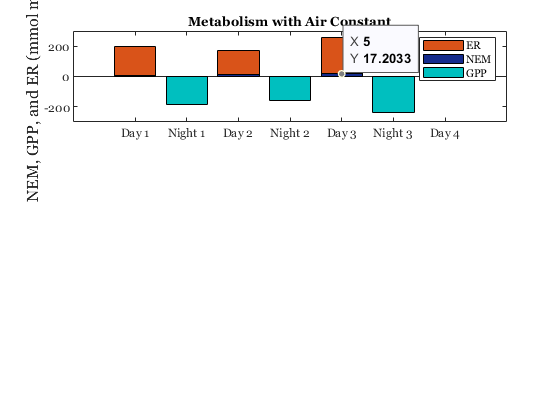


figure
ax1=subplot(4,1,4);
ax.XAxisLocation = 'origin';
bar(1,GPP1,'FaceColor',red)
hold on
bar(1,NEM1,'FaceColor',navy)
bar(2,DRR2,'FaceColor',teal)
bar(3,GPP2,'FaceColor',red)
bar(3,NEM2,'FaceColor',navy)
bar(4,DRR3,'FaceColor',teal)
bar(5,GPP3,'FaceColor',red)
bar(5,NEM3,'FaceColor',navy)
bar(6,DRR4,'FaceColor',teal)
hold on
ylabel('NEM, GPP, and ER (mmol m^-^2 d^-^1)','FontName','Georgia','FontSize',12)
title('Metabolism with Air Constant','FontName','Georgia','FontSize',18)
xticks([1 2 3 4 5 6])
xticklabels({'Day 1','Night 1','Day 2', 'Night 2', 'Day 3', 'Night 3'})
legend('ER','NEM','GPP')
set(ax1,'FontName','Georgia')
ylim([-300 300])

%set(xticklabels,'FontName','Georgia')
%set(ax,'FontName','Georgia','XTick','XTickLabel',{'10/24','','10/25'});

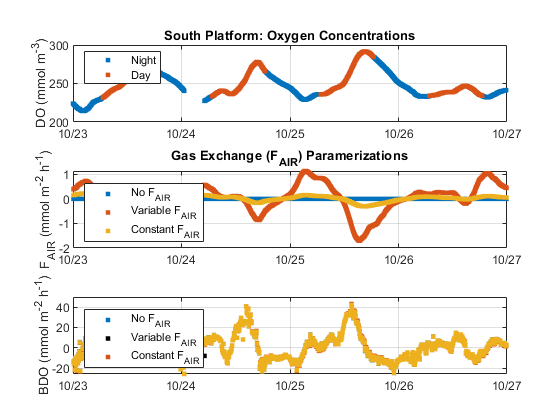

figure 
subplot(3,1,1)
plot(south.dn(PM),Cw(PM)*1000,'.','MarkerSize',10) % convert to mmol/m3
hold on
plot(south.dn(AM),Cw(AM)*1000,'.','MarkerSize',10)
datetick
grid on
ylabel('DO (mmol m^-^3)')
title('South Platform: Oxygen Concentrations')
legend('Night','Day','Location','NW')

subplot(3,1,2)
plot(dn,zeros(1,length(dn)),'.','MarkerSize',10)
hold on
plot(dn,-Fair,'.','MarkerSize',10)
plot(dn,Fair_constant,'.','MarkerSize',10)
datetick
grid on
legend('No F_A_I_R','Variable F_A_I_R','Constant F_A_I_R','Location','SW')
ylabel('F_A_I_R (mmol m^-^2 h^-^1)')
title('Gas Exchange (F_A_I_R) Paramerizations')

subplot(3,1,3)
plot(dn,delDOdt0,'.','MarkerSize',10,'Color',blue)
hold on
plot(dn,delDOdtkmean,'.k','MarkerSize',10)
plot(dn,delDOdt,'.','MarkerSize',10,'Color',red)
plot(dn,delDOdtk,'.','MarkerSize',10,'Color',yellow)
datetick
grid on
ylabel('BDO (mmol m^-^2 h^-^1)')
legend('No F_A_I_R','Variable F_A_I_R','Constant F_A_I_R','Location','SW')

NEP1 = sum(delDOdt(AM1))/10 

NEP1 = 105.5460

NR2 = sum(delDOdt(PM2))/10 %mmol/m2/hr % changed to 10 because 10 readings in an hour 

NR2 = NaN

NEP2 = sum(delDOdt(AM2))/10 

NEP2 = 94.4677

NR3 = sum(delDOdt(PM3))/10 %mmol/m2/hr 

NR3 = -85.0961

NEP3 = sum(delDOdt(AM3))/10 %mmol/m2/hr 

NEP3 = 143.3876

NR4 = sum(delDOdt(PM4))/10 %mmol/m2/hr 

NR4 = -120.0128

NEP4 = sum(delDOdt(AM4))/10 %mmol/m2/hr 

NEP4 = 5.7577


NEM1 = NEP1 + NR2

NEM1 = NaN

NEM2 = NEP2 + NR3

NEM2 = 9.3716

NEM3 = NEP3 + NR4

NEM3 = 23.3747


meanR2 = nanmean(delDOdt(PM2))

meanR2 = -7.6162

meanR3 = nanmean(delDOdt(PM3))

meanR3 = -6.9751

meanR4 = nanmean(delDOdt(PM4))

meanR4 = -9.8371


DRR2 = meanR2*24

DRR2 = -182.7889

DRR3 = meanR3*24

DRR3 = -167.4021

DRR4 = meanR4*24

DRR4 = -236.0908


GPP1 = NEP1 + length(AM1)/10*abs(meanR2)

GPP1 = 196.1788

GPP2 = NEP2 + length(AM2)/10*abs(meanR3)

GPP2 = 176.7737

GPP3 = NEP3 + length(AM3)/10*abs(meanR4)

GPP3 = 259.4655

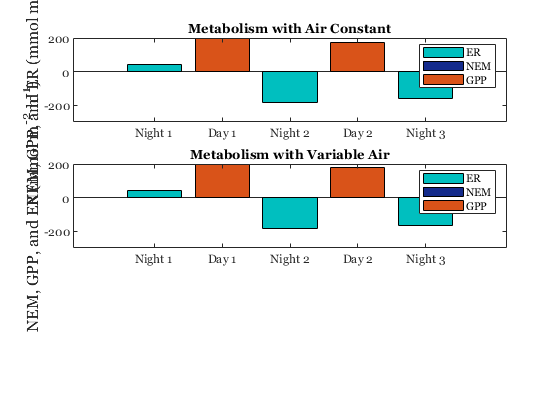


ax2 = subplot(3,1,2);
ax.XAxisLocation = 'origin';
bar(1,DRR1,'FaceColor',teal)
hold on
bar(2,NEM1,'FaceColor',navy)
hold on
bar(2,GPP1,'FaceColor',red)
hold on
bar(3,DRR2,'FaceColor',teal)
hold on
bar(4,NEM2,'FaceColor',navy)
%ax.YAxisLocation = 'origin';
hold on
bar(5,DRR3,'FaceColor',teal)
hold on
bar(4,GPP2,'FaceColor',red)
hold on
ylabel('NEM, GPP, and ER (mmol m^-^2 h^-^1)','FontName','Georgia','FontSize',12)
title('Metabolism with Variable Air','FontName','Georgia','FontSize',18)
xticks([1 2 3 4 5])
xticklabels({'Night 1','Day 1', 'Night 2', 'Day 2', 'Night 3'})
legend('ER','NEM','GPP')
set(ax2,'FontName','Georgia')
ylim([-300 200])

%set(xticklabels,'FontName','Georgia')
%set(ax,'FontName','Georgia','XTick','XTickLabel',{'10/24','','10/25'});


% For Fair = 0 
NEP1 = sum(delDOdt0(AM1))/10 

NEP1 = 103.7767

NR2 = sum(delDOdt0(PM2))/10 %mmol/m2/hr % changed to 10 because 10 readings in an hour 

NR2 = NaN

NEP2 = sum(delDOdt0(AM2))/10 

NEP2 = 92.6170

NR3 = sum(delDOdt0(PM3))/10 %mmol/m2/hr 

NR3 = -80.3020

NEP3 = sum(delDOdt0(AM3))/10 %mmol/m2/hr 

NEP3 = 137.5682

NR4 = sum(delDOdt0(PM4))/10 %mmol/m2/hr 

NR4 = -122.0915

NEP4 = sum(delDOdt0(AM4))/10 %mmol/m2/hr 

NEP4 = 8.2002


NEM1 = NEP1 + NR2

NEM1 = NaN

NEM2 = NEP2 + NR3

NEM2 = 12.3150

NEM3 = NEP3 + NR4

NEM3 = 15.4767


meanR2 = nanmean(delDOdt0(PM2))

meanR2 = -7.6218

meanR3 = nanmean(delDOdt0(PM3))

meanR3 = -6.5821

meanR4 = nanmean(delDOdt0(PM4))

meanR4 = -10.0075


DRR2 = meanR2*24

DRR2 = -182.9229

DRR3 = meanR3*24

DRR3 = -157.9711

DRR4 = meanR4*24

DRR4 = -240.1799


GPP1 = NEP1 + length(AM1)/10*abs(meanR2)

GPP1 = 194.4760

GPP2 = NEP2 + length(AM2)/10*abs(meanR3)

GPP2 = 170.2861

GPP3 = NEP3 + length(AM3)/10*abs(meanR4)

GPP3 = 255.6566

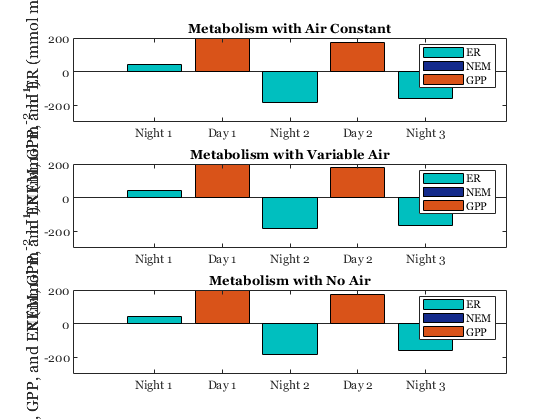


ax3 = subplot(3,1,3);
ax.XAxisLocation = 'origin';
bar(1,DRR1,'FaceColor',teal)
hold on
bar(2,NEM1,'FaceColor',navy)
hold on
bar(2,GPP1,'FaceColor',red)
hold on
bar(3,DRR2,'FaceColor',teal)
hold on
bar(4,NEM2,'FaceColor',navy)
%ax.YAxisLocation = 'origin';
hold on
bar(5,DRR3,'FaceColor',teal)
hold on
bar(4,GPP2,'FaceColor',red)
hold on
ylabel('NEM, GPP, and ER (mmol m^-^2 h^-^1)','FontName','Georgia','FontSize',12)
title('Metabolism with No Air','FontName','Georgia','FontSize',18)
xticks([1 2 3 4 5])
xticklabels({'Night 1','Day 1', 'Night 2', 'Day 2', 'Night 3'})
legend('ER','NEM','GPP')
set(ax3,'FontName','Georgia')
ylim([-300 200])

%set(xticklabels,'FontName','Georgia')
%set(ax,'FontName','Georgia','XTick','XTickLabel',{'10/24','','10/25'});
